%Make a Bode plot for G = 5 (0.5s + 1)e^–0.5s/(20s + 1)
%(4s + 1)
close all
gain = 6;
tdead = 2;
num = [1 1];
den = [8 6 1];
G = tf (gain*num, den); %Define the system as a transfer
Pnd1 = pade(G,gain)


Pnd1 =
 
      6 s + 6
  ---------------
  8 s^2 + 6 s + 1
 
Continuous-time transfer function.



% P13 = pade(G,inf,1,6);
% size(P13)
% P3 = pade(G,inf,inf,6);
% size(P3)
% P3.OutputDelay

%function
points = 500; %Define the number of points
ww = logspace (-2, 2, points); %Frequencies to be evaluated
[mag, phase, ww] = bode (G,ww); % Generate numerical

%values for Bode plot
AR = zeros (points, 1); % Preallocate vectors for Amplitude

%Ratio and Phase Angle
PA = zeros (points, 1);
for i = 1 : points
AR(i) = mag (1,1,i)/gain; %Normalized AR
PA(i) = phase (1,1,i) - ((180/pi) *tdead*ww(i));
end

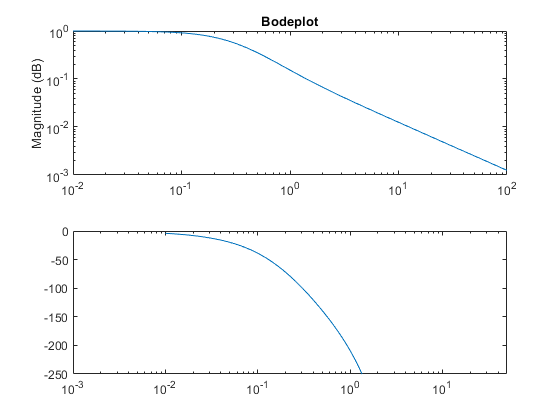

figure
subplot (2,1,1)
loglog(ww, AR)
axis ([0.01 100 0.001 1])
title ('Bodeplot')
ylabel('Magnitude (dB)')
subplot (2,1,2)
semilogx(ww,PA)
axis ([0.001 50 -250 0])

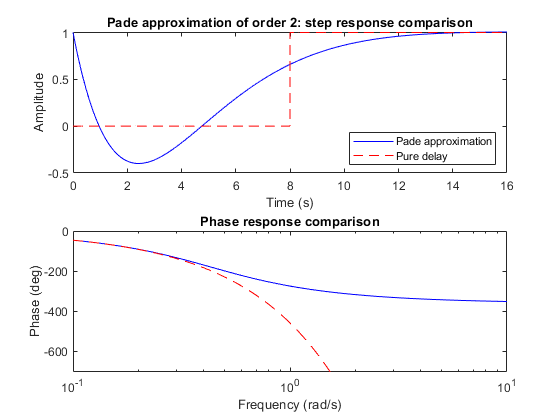

pade(8,2)
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')